# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');
warning('off','all')

# **Lab 4 - Triangulation**

## **Using RANSAC**

This whole lab is basically concerned with the camera equation


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\lambda u=P\;U$$


For the uncalibrated case, $u$ is a 3-vector with the coordinates of a point in the image (and an added 1)


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u=\left\lbrack \begin{array}{c}
x\\
y\\
1
\end{array}\right\rbrack$$


and $U$ is a 4-vector containing the coordinates of the corresponding 3D point along with a 1 in its last element. A function

sigma = 0.5;
[Ps, us, U_true] = triangulation_test_case(sigma)

Ps = 1×2 cell array
    {3×4 double}    {3×4 double}


us =   -98.9467 -132.6361
 -178.3482 -204.6438


U_true =     0.3717
    0.5504
    0.3845


is provided for creating a simple test case where you know the correct answer (`U_true`). Gaussian noise of standard deviation `sigma` is added to the image points. Use this example to evaluate your minimal solver.

**Ex 4.1**     Make a minimal solver for the triangulation problem, that is, a function 

U = minimal_triangulation(Ps, us)

U =     0.3717
    0.5499
    0.3761


that takes two camera matrices, `Ps`, and two image points, `us`, and triangulates a 3D point. The image points are a 2 x 2 array whereas the camera matrices is a cell list with one camera matrix in each cell. 

Recall that $\lambda$ is the *depth*. Points with negative depth would lie behind the camera, so negative depths indicate that something is wrong.

**Ex 4.2**     Make a function 

positive = check_depths(Ps, U)

positive =      1     1


that takes *N* camera matrices, `Ps`, and a 3D point, `U`, and checks the depth of `U` in each of the cameras. The output should be a an array of boolean values of length *N* that indicates which depths were positive. (Matlab will print boolean values as zeros and ones, so don’t be confused by this.)

**Ex 4.3**     Make a function 

errors = reprojection_errors(Ps, us, U)

errors =     0.0000    0.0993


that takes *N* camera matrices, `Ps`, *N* image points, `us`, and a 3D point, `U`, and computes a vector with the reprojection errors, that is, the lengths of the reprojection residuals. If a point has negative depth, set the reprojection error to `Inf`. 

**Ex 4.4**     Make a function 

threshold =  2

threshold = 2

[U, nbr_inliers] = ransac_triangulation(Ps, us, threshold) 

U =     0.3717
    0.5499
    0.3761


nbr_inliers = 2

that implements triangulation using RANSAC. Use the number of outliers as loss function. A measurement is deemed as an outlier if the depth is negative or if the reprojection error is larger than `threshold`. 

In `sequence.mat` you find a struct array `triangulation_examples` with triangulation examples. Each example (3D point) has a cell list of camera matrices `Ps` and a 2 x N-array `us` with image points. It will take some time to triangulate all 32183 examples so start with the first 1000 or so. We used a RANSAC threshold of 5 pixels. 

**Ex 4.5**     Make a script `triangulate_sequence` that runs `ransac_triangulation` for all (or at least 1000) of the examples from `sequence.mat`. Store all triangulated points with at least two inliers and plot them using `scatter3`. There will always be a few outliers among the estimated 3D points that make it harder to view the plot. You can use the provided `clean_for_plot.m` to clean it up a bit. 

triangulate_sequence   % Script that you need to create

Uc = clean_for_plot(Us)

Uc =   -17.3490  -18.1840  -15.8041  -14.0262  -16.7281  -16.5155  -14.9072  -17.9609  -17.2011  -16.6080  -14.5100  -12.6324  -12.6411  -12.6055  -13.0322  -17.6697  -17.7924  -17.5260  -16.9665  -12.6863  -13.0217  -13.0816  -18.3379  -18.1508  -17.2386  -17.1353  -17.0483  -16.9462  -16.9291  -16.7453  -15.6503  -12.6089  -13.0499  -13.0104  -13.1156  -12.9241  -18.3870  -18.2610  -18.0141  -17.8759  -17.5179  -17.5879  -17.3953  -17.3708  -17.4014  -17.4056  -17.3060  -17.1663  -17.1555  -17.1210
    3.5938    4.9191    5.4098    5.5636    5.3092    5.2788    5.5212    5.2435    5.4865    5.4589    5.7223    2.1027    2.4410    2.4463    5.1484    5.2648    5.2247    5.4225    5.4634    3.1771    5.0631    6.0765    5.1005    5.2072    5.6157    5.6098    5.5781    5.6025    5.5827    5.2484    5.4761    3.2772    5.3385    5.3488    5.7157    5.8697    5.0679    5.2197    5.1777    5.5834    5.3661    5.3091    5.4494    5.5062    5.2604    5.2623    5.6559    5.5268    5.5444    

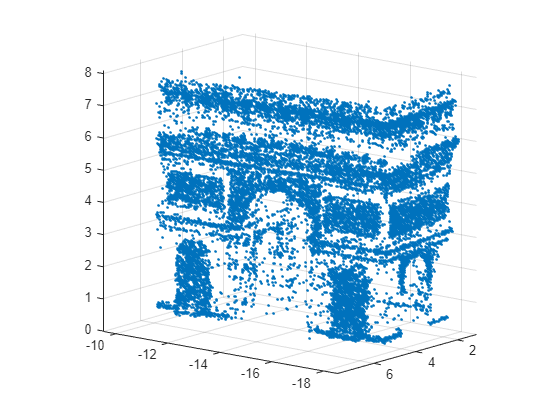


scatter3(Uc(1,:),Uc(2,:),Uc(3,:),'.')

axis equal

xlim([-18.57 -9.50])
ylim([1.08 7.79])
zlim([0.00 8.10])
view([-141.23 13.20])
ax = gca;
chart = ax.Children(1);
datatip(chart,-16.28,3.561,0.9462);

Can you recognize the building? 

**Write your answer with explanation as a comment here.**

% The plot is a collection of dots that seems to form the shape of the
% building, the building seems to be "Arc de Triomphe" in Paris

## Least squares triangulation 

In this part of the lab you will solve the tringulation problem through least squares. Just as in the case of registration, the following pipeline is recommended: 

    - Use RANSAC to obtain a rough estimate of the parameters (*U*). 

    - Remove all measurements which are outliers with respect to these parameters. 

    - Estimate the least squares parameters using the remaining measurements. 

Note that in this case a *measurement* is a pair consisting of an image point $u_i$ and a camera matrix $P_i$. Don’t forget that points with negative depths should be outliers. 

**Ex 4.6**     Consider a camera matrix 

                        $P_i =\left\lbrack \begin{array}{c}
\longleftarrow a_i^T \longrightarrow \\
\longleftarrow b_i^T \longrightarrow \\
\longleftarrow c_i^T \longrightarrow 
\end{array}\right\rbrack$ ,

a 3D point *U* and an image point $u_i$. Write the formula for the reprojection error $r_i \left(U\right)$ below.

**Your answer here:**


$$r_i \left(U\right)=\left\lbrack \begin{array}{c}
\frac{a_i^T \;U}{c_i^T \;U}-x_{u_i } \\
\frac{b_i^T \;U}{c_i^T \;U}-y_{u_i } 
\end{array}\right\rbrack$$


As you can see, the residuals are no longer linear, so computing a least squares solution will be significantly harder than in the previous lab. In fact, we cannot be sure to find the least squares solution. What we can do is to use local optimization to reduce the sum of squared residuals. We start at the solution produced by Ransac and use a few Gauss-Newton iterations.

**Ex 4.7**     Make a function  

that takes a cell list `Ps` with *N* cameras, a 2 x *N* array `us` of image points and a 3 x 1 array `U`, and computes a 2*N* x 1 array with all the reprojection residuals stacked into a single vector/array. A reprojection residual is a 2D vector corresponding to the difference between the original measurement and the projected point. The stacked vector is the $\bar{r}$ from the lecture notes (page 99).


all_residuals_7 = compute_residuals(triangulation_examples(1).Ps, triangulation_examples(1).xs, Us(:,1))

all_residuals_7 =   -13.0389
  -14.1006
   -6.7025
   -9.8503
   -3.6658
   -8.1082
   -0.0000
   -0.0000
   -1.6248
    0.9138


**Ex 4.8**     Find formulas for the partial derivatives in the Jacobian of $\bar{r}$. The Jacobian should be a 2N x 3- matrix. (Hint: you can start by finding the formula to the Jacobian of the i-th residual, which is a 2x3 matrix.)

## Your answer here:


$$J_i =\frac{\partial r_i \left(U\right)}{\partial U}=\left\lbrack \begin{array}{ccc}
\frac{{\partial r}_{i,x} }{\partial U_1 } & \frac{{\partial r}_{i,x} }{\partial U_2 } & \frac{{\partial r}_{i,x} }{\partial U_3 }\\
\frac{{\partial r}_{i,y} }{\partial U_1 } & \frac{{\partial r}_{i,y} }{\partial U_2 } & \frac{{\partial r}_{i,y} }{\partial U_3 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\longleftarrow \frac{a_i^T \left(c_i^T \;U\right)-\left(a_i^T \;U\right)c_i^T }{{\left(c_i^T \;U\right)}^2 }\longrightarrow \\
\longleftarrow \frac{b_i^T \left(c_i^T \;U\right)-\left(b_i^T \;U\right)c_i^T }{{\left(c_i^T \;U\right)}^2 }\longrightarrow 
\end{array}\right\rbrack$$


**Ex 4.9**     Make a function 

that computes the Jacobian given a 3 x 1- vector `U` and a cell array of camera matrices `Ps`. 

% usage example
all_residuals_9 = compute_jacobian(triangulation_examples(1).Ps, Us(:,1))

all_residuals_9 =   -16.1530   70.2096  140.0627
 -154.0129  -16.6546   -6.9176
  -22.7905   71.1312  142.2999
 -155.3939  -24.8213   -9.1976
  -26.9039   67.2874  139.8006
 -151.7820  -31.2205  -10.4022
  -27.6971   65.7785  139.4225
 -149.8395  -36.7097   -8.4303
  -28.2934   66.3321  140.2360
 -149.8506  -40.6455   -7.0374


**Ex 4.10**     Use these functions to make a function 

that uses an approximate 3D point `Uhat` as a starting point for Gauss-Newton’s method. Use five GaussNewton iterations. Print the sum of squared residuals after each Gauss-Newton step to verify that it decreases. 

% usage example
Uref = refine_triangulation(triangulation_examples(1).Ps, triangulation_examples(1).xs, Us(:,1))

Uref =   -17.4131
    3.8202
    6.7842


**Ex 4.11**     Try your `refine_triangulation` on the data in `gauss_newton.ma`t. First we will plot the points given in `Uhat`, then refine each point using your function and plot the results using `scatter3`. You should see an improvement. 

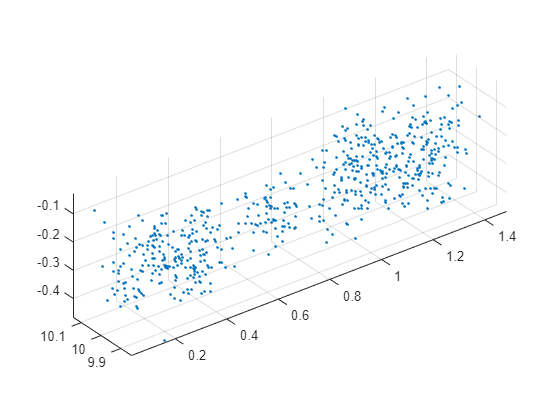

% don't forget to plot your results
load gauss_newton
scatter3(Uhat(1,:),Uhat(2,:),Uhat(3,:),'.') 
axis equal

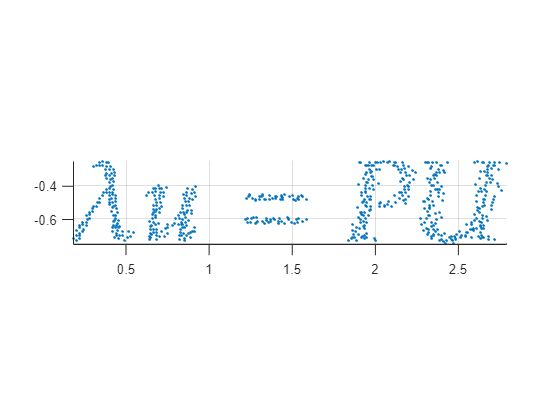


Ps_11 = {P , P_tilde};

N = size(Uhat,2);
Uref = zeros(3,N);
for i = 1:N
    Uref(:,i) = refine_triangulation(Ps_11, [u(:,i), u_tilde(:,i)], Uhat(:,1));
end
scatter3(Uref(1,:),Uref(2,:),Uref(3,:),'.'), axis equal

**Ex* 4.12**     Compute the camera positions for the data in `gauss_newton.mat` and plot them together with the estimated 3D points. Try to understand why the noise in the estimated points looks as it does. 

% YOUR CODE HERE; don't forget to plot your results



For the next exercise try the following way to match features, 

The approximate option makes it go significantly faster. A Lowe ratio of 0.9 is very high, but it makes the model more *dens*e. 

**Ex 4.13**     There are images `duomo.jpg` and `duomo_tilde.jpg` in the lab folder and also a data file `duomo.mat` with two camera matrices. Extract SIFT features from the two images using `detectSIFTFeatures` and `extractFeatures`, then match them using `matchFeatures`. Also store the color of each SIFT point. It doesn’t matter from which of the images you select the color information. 

Use your triangulation code (don’t forget r`efine_triangulation`) to triangulate the points and plot them with the right color using `scatter3`. Again, you can use `clean_for_plot.m` to remove outliers among the estimated 3D points. Beware that triangulating all the points will take a little time so work with a subset until you are sure that the code works.

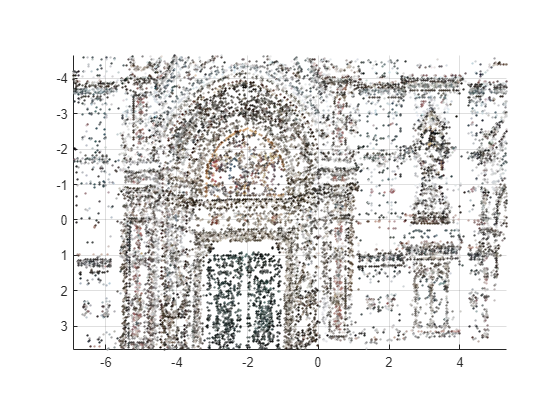

% Load the data file containing camera matrices
load duomo

% Load the images
img_src = rgb2gray(imread("duomo.jpg"));
img_trg = rgb2gray(imread("duomo_tilde.jpg"));

% Extracting SIFT Features from doumo and doumo_tilde
src_points = detectSIFTFeatures(img_src);
[feature_1, pts_1] = extractFeatures(img_src , src_points);
trg_points = detectSIFTFeatures(img_trg);
[feature_2, pts_2] = extractFeatures(img_trg , trg_points);

% Match the SIFT features
corrs = matchFeatures(feature_1, feature_2,'Method','Approximate', 'MaxRatio', 0.5, 'MatchThreshold', 100);

% Extract color information from one of the images

color_img = imread('duomo.jpg');
keypoint_coords = round(pts_1(corrs(:,1)).Location);

colors = impixel(color_img, keypoint_coords(:,1), keypoint_coords(:,2)) / 255;


u = pts_1(corrs(:, 1),:);
u_tilde = pts_2(corrs(:, 2),:);

Ps_13 = {P , P_tilde};
threshold_13 = 20;
U = zeros(3, size(corrs,1));
inliers = [];

for i = 1 : size(corrs, 1)
    xs = horzcat(u(i,:).Location' , u_tilde(i,:).Location');
    [Uhat, nbr_inliers] = ransac_triangulation(Ps_13, xs, threshold_13);
    U(:,i) = refine_triangulation(Ps_13, xs , Uhat);
end

% Remove outliers and plot the results
[Us_clean, removed_indices] = clean_for_plot(U);

colors(removed_indices,:)= [];

scatter3(Us_clean(1,:),Us_clean(2,:),Us_clean(3,:),3,colors,'filled')
axis equal;
view([-0 -90])

## **Essential Matrix**

The two exercises below are optional and therefore marked with *****.

**Ex* 4.14**     Load the data in `P.mat`. There you will find two calibrated camera matrices, `P1` and `P2`. Make a function 

that computes the essential matrix `E` from `P1` and `P2` .

load P.mat
E = essentialMatrix(P1,P2)

E =    -1.1104   -4.7697    0.4347    4.4724    0.9985   -0.9494
   -6.3623    2.1601   -1.2967   -0.7075   -5.0608    3.5782
    2.1371    4.3909   -0.2216   -4.9201    1.8751   -1.0347


**Ex* 4.15**     Similar to the reprojection error in the triangulation problem, the essential matrix can also be used for outlier detection using the residual


$$r^2 =\frac{\left|{\tilde{x} }^T \;E\;x\;\right|}{{\left\|S\;E\;x\right\|}^2 +{\left\|S\;E^T \;\;\tilde{x} \right\|}^2 \;},\;\;\;\;\;\;\;\;\;\;S=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


where $x$ and $\tilde{x}$ are the image projections of a 3D point *X* using some arbitrary camera matrices $P$ and $\tilde{P}$, respectively. Note that $r$ does not depend on X. Assuming that you are using a similar threshold for outlier detection, for a set of pixel correspondences, you would get `I1` inliers if you use the residual from the triangulation problem and `I2` inliers if you used the residual from (4.4). Which one is greater, `I1` or `I2`? Why? 